# LiDARDRONE

MRK 1.1

clear all;
clc;

## Define the map dimensions, walls and obstacles

% Define max map dimensions
x_map_size = 10;
y_map_size = 10;

% Define the drone's starting and ending point in ABS REF FRAME
start = [1, 1];  % Punto di partenza
goal = [6.5, 6.5]; % Punto di arrivo

% Define space limitation in drone exploring map skils
space_limits = [0 x_map_size 0 y_map_size]; %(x min, x max, y min, y max)

% Define the walls and obstacles in the map
% Comment the unwanted map type
% Map 1
obstacles = [0, 0, 10, 0.1;     %
             0, 0, 0.1, 10;     % these are the walls
             10, 0, 0.1, 10.1;  %
             0, 10, 10, 0.1;    %
             2.3, 1.5, 0.1, 3;
             2.3, 4.5, 2, 0.1;
             4.3, 4.5, 0.1, 1.7;
             1.4, 6.2, 3, 0.1;
             1.4, 6.3, 0.1, 2.4;
             4, 1.5, 4.5, 0.1;
             5.2, 3, 2.8, 0.1;
             5, 8.5, 3, 0.1;
             7.9, 4, 0.1, 4.5;
             6, 4, 0.1, 3;];    % [x, y, larghezza, altezza]

% Iinflation factor applied to the obstacles
inflate = 0.3;
inflated_obstacles = zeros(size(obstacles));
for i = 1:height(obstacles)
    inflated_obstacles(i, 1) = obstacles(i, 1) - inflate; % x iniziale spostato a sinistra
    inflated_obstacles(i, 2) = obstacles(i, 2) - inflate; % y iniziale spostato in basso
    inflated_obstacles(i, 3) = obstacles(i, 3) + 2*inflate; % larghezza aumentata
    inflated_obstacles(i, 4) = obstacles(i, 4) + 2*inflate; % altezza aumentata
end

% Map 2
% ...

Show the created map with inflated boards

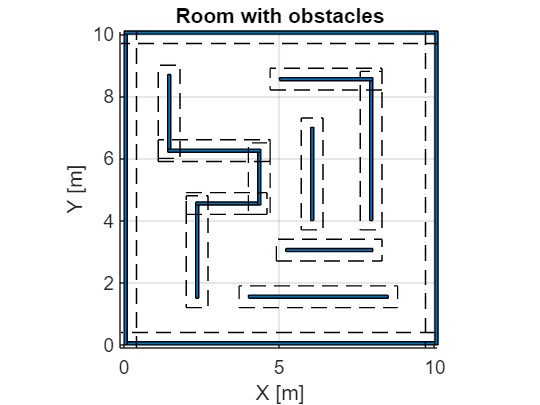

figure (1);
for i = 1:size(obstacles, 1)
    rectangle('Position', obstacles(i, :), 'FaceColor', '#0072BD');
end

hold on;
for i = 1:size(inflated_obstacles, 1)
    rectangle('Position', inflated_obstacles(i, :), 'EdgeColor', 'k', 'LineStyle', '--');
end

grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
hold off;

## Build the RRT algorith to explore the space (ONE STEP TIME EXAMPLE)

% % Parameter declaration
% step_size = 0.3; 
% n_iterations = 20; 
% goal_threshold = 0.5; 
% 
% % RRT initialization
% rrt_tree = start; % RRT starting point
% parent_indices = 0; % RRT parent index
% 
% % RRT tree generation
% for i = 2:n_iterations % from 2-> starting point at the moment is given
%     % If point is inside the obstacles, avoid
% 
%     flag1 = true;
%     flag2 = true;
%     while flag1 == true || flag2 == true
% 
%         % Random point (MODIFY HERE THE EXPLORATION SPACE FOR EACH DRONE IF REQUIRED)
%         random_point = [rand() * x_map_size, rand() * y_map_size];
% 
%         if isInObstacle(random_point, inflated_obstacles)
%             flag1 = true;
%         else
%             flag1 = false;
%         end
% 
%         % Find nearest point wrt RRT tree
%         distances = sqrt(sum((rrt_tree - random_point).^2, 2));
%         [min_distance, nearest_idx] = min(distances);
% 
%         % Identify new RRT point
%         direction = random_point - rrt_tree(nearest_idx, :);
%         unit_direction = direction / norm(direction);
%         new_point = rrt_tree(nearest_idx, :) + step_size * unit_direction;
% 
%         % Check compenetrarion of new point wrt the obstacles
%         if isInObstacle(new_point, inflated_obstacles)
%             flag2 = true;
%         else
%             flag2 = false;
%         end
% 
%     end
% 
%     % Add the new point to the RRT tree
%     rrt_tree = [rrt_tree; new_point];
%     parent_indices = [parent_indices; nearest_idx];
% 
%     % % Verify if the goal is reached
%     % if norm(new_point - goal) < goal_threshold
%     %     disp('Goal raggiunto!');
%     %     break;
%     % end
% end

Visualize RRT tree on the map

% figure (2);
% hold on;
% %plot(rrt_tree(:, 1), rrt_tree(:, 2), 'O'); % Visualizza i punti
% for i = 2:size(rrt_tree, 1)
%     plot([rrt_tree(parent_indices(i), 1), rrt_tree(i, 1)], ...
%          [rrt_tree(parent_indices(i), 2), rrt_tree(i, 2)], 'LineStyle', '-', 'Color', '#A2142F', 'Marker' , '.');
% end
% 
% for i = 1:size(obstacles, 1)
%     rectangle('Position', obstacles(i, :), 'FaceColor', '#0072BD');
% end
% 
% hold on;
% for i = 1:size(inflated_obstacles, 1)
%     rectangle('Position', inflated_obstacles(i, :), 'EdgeColor', 'k', 'LineStyle', '--');
% end
% 
% grid on;
% axis equal; 
% xlabel('X [m]');
% ylabel('Y [m]');
% xlim([-0.10 x_map_size + 0.1]);
% ylim([-0.10 y_map_size + 0.1]);
% title('RRT tree');
% hold off;

## LiDAR test example

lidar_position = [5, 4];
lidar_angles = linspace(0, 360, 100);  % 100 scanning lines
max_range = 2;
lidar_dist_res = 0.01; 
[point_abs,point_abs_clean, point_rel, dist_rel] = Lidar_scan(obstacles, lidar_position, lidar_angles, max_range, lidar_dist_res);

Plot Lidar example

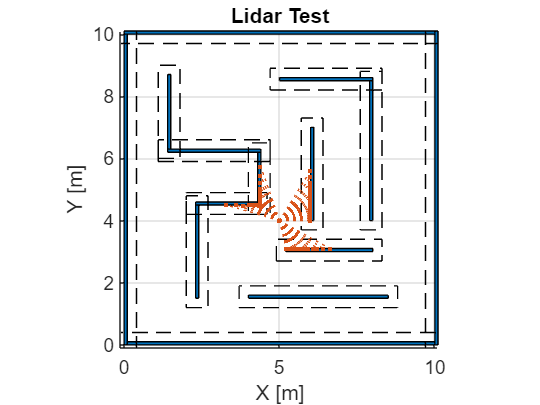

figure(3);
% Plot obstacles
for i = 1:size(obstacles, 1)
    hold on
    rectangle('Position', obstacles(i, :), 'FaceColor', '#0072BD');
end
% Plot inflated obstacles
for i = 1:size(inflated_obstacles, 1)
    rectangle('Position', inflated_obstacles(i, :), 'EdgeColor', 'k', 'LineStyle', '--');
end
% Plot LiDAR result
for angle_step = 1:length(lidar_angles)-1
    angle = lidar_angles(angle_step);
    ray_direction = [cosd(angle), sind(angle)];
    hit_point = point_abs(angle_step, :);
    if ~all(hit_point == 0) % Plot just hit points

        plot([lidar_position(1), hit_point(1)], [lidar_position(2), hit_point(2)],'LineStyle', ':', 'Color', '#D95319', 'Marker' , "."'); % Plot ray
    end
end
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Lidar Test');
hold off;

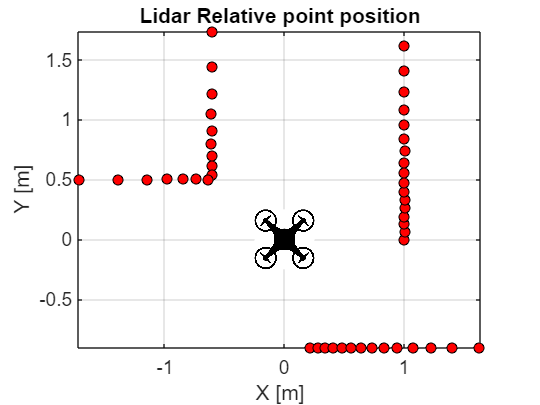


% Plot LiDAR result in relative envioment
plot(point_rel(:, 1), point_rel(:, 2), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black', 'MarkerSize', 5); % Plot ray
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
title('Lidar Relative point position');


img = imread('drone.jpg'); % Sostituisci con il percorso dell'immagine
imageWidth = 0.5; % Larghezza desiderata dell'immagine
imageHeight = 0.5; % Altezza desiderata dell'immagine
xPos = 0 - imageWidth/2; % Posizionamento sull'asse x
yPos = 0 - imageHeight/2; % Posizionamento sull'asse y

% Aggiungi l'immagine alla posizione specificata
image('CData', img, 'XData', [xPos, xPos + imageWidth], 'YData', [yPos, yPos + imageHeight]);

## LiDAR LANDMARK RECOGNITION TEST

distanza tra punti molto larga significa che potrebbe non essere un landmark ma un out of range tra due scan

## Reconstruction of the features

All the data collected by the measurement linked with a specific point in the "Profile" matrix. In this way, is possible to collect in the best way all the laser points with their specifications.

Feature-identification of the points will be:

- Curvature

- Distance (already extracted from unity)

- PCA (var1, var2)

- End point (type 2 or type 3)

- Time

- Point coordinates wrt lidar

- Laser angle wrt lidar

- Point coordinates wrt ground (absolute, just for plots)

-  Ground Truth (absolute, just for plots)

Res = 2;
i = 1 + Res;

while i+Res < length(point_rel)

    % Curvature

    F = [point_rel(i-Res,1),point_rel(i-Res,2), 0];
    G = [point_rel(i,1),point_rel(i,2), 0];
    H = [point_rel(i+Res,1),point_rel(i+Res,2), 0];

    f = norm(G - H);
    g = norm(F - H);
    h = norm(G - F);
    A = norm(cross(H - F, G - F) / 2);
    Profile(i, 1) = 4 * A / (f * g * h); %curvature


    % Distance 

    Profile(i, 2) = dist_rel(i); %distance


    %PCA

    X = [point_rel(i-Res:i+Res,1),point_rel(i-Res:i+Res,2)];
    [Dir, score, Var] = pca(X); 
    %theta = angle(Dir(1,1) + 1i*Dir(2,1)) * 180/pi; 
    Profile(i, 3) = sqrt(Var(1)); %Var1
    Profile(i, 4) = sqrt(Var(2)); %Var2

    % relative position
    Profile(i, 5) = point_rel(i, 1);  
    Profile(i, 6) = point_rel(i, 2); 
    
    % RESUME: The profile matrix contains

    % curvature
    % distance
    % var1
    % var2
    % positionx
    % potitiony


    %End Point TO BE CALCULATED ONLY WHEN MULTIPLE SCANS HAPPENDS

    % if abs(point_rel(i+Res,4)) - abs(point_rel(i+Res-1,4)) > 1 %soglia distanza in [m]
    %    %disp (abs(Cartesian_matrix(i+Res,4)) - abs(Cartesian_matrix(i+Res-1,4)));
    %    Profile(i+Res-1,5) = 2;
    %    %Profile(i+Res,5) = 3;%end point method
    % end


    % Time

    %Profile(i,6) = Cartesian_matrix(i,3);


    %X wrt Lidar

    % Profile(i,7) = lidar_position(i,1); 


    %Z wrt Lidar

    %Profile(i,8) = lidar_position(i,2); 


    % Angle of the lidar scan

    % Profile(i,9) = ScanAngle(i,1);


    %X wrt abs just for plot

    %Profile(i,10) = Cartesian_matrix(i,5); 


    %Z wrt abs just for plot

    %Profile(i,11) = Cartesian_matrix(i,6); 


    %Ground truth x just for plot

    %Profile(i,12) = Cartesian_matrix(i,7);

    %Ground truth z just for plot

    %Profile(i,13) = Cartesian_matrix(i,8);

    i = i+1;
end

Plots about curavture and var std

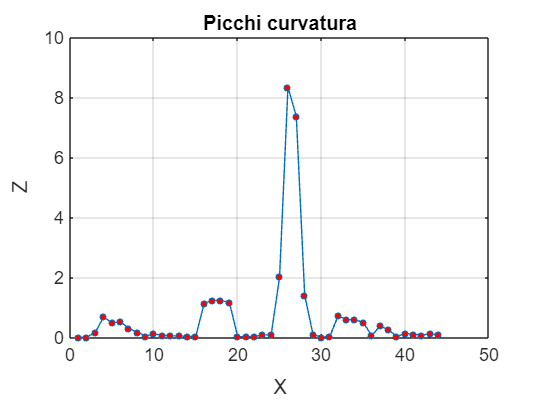

figure (); 
plot(1:length(Profile), Profile(:,1), '-o', 'MarkerSize', 3, 'MarkerFaceColor', 'r');
title('Picchi curvatura');
xlabel('X');
ylabel('Value');
grid on;

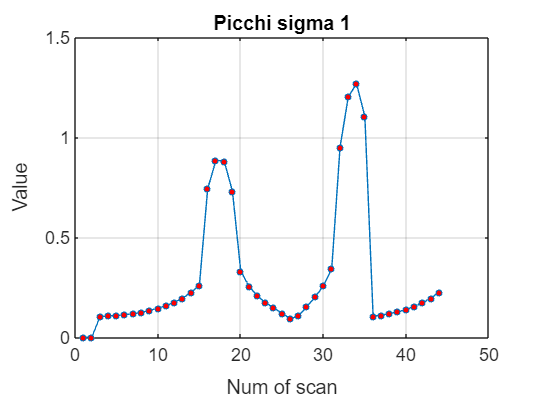



figure ();
plot(1:length(Profile), Profile(:,3), '-o', 'MarkerSize', 3, 'MarkerFaceColor', 'r');
title('Picchi sigma 1');
xlabel('Num of scan');
ylabel('Value');
grid on;

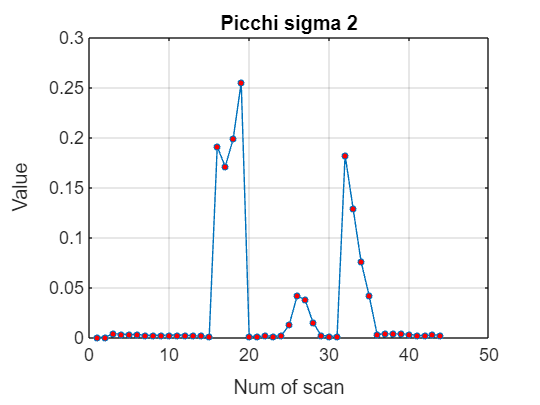



figure ();
plot(1:length(Profile), Profile(:,4), '-o', 'MarkerSize', 3, 'MarkerFaceColor', 'r');
title('Picchi sigma 2');
xlabel('Num of scan');
ylabel('Value');
grid on;

Peak curvature filtering with threshold

Peak_vector = zeros(length(point_rel),2);
i = 1;
while i<=length(Profile)
    if Profile(i, 1) >= 1 %filtering threshold
        Peak_vector(i,1) = Profile(i, 1);
    end
    i = i+1;
end

% Remove other points putting zero values
i = 1;
while i<=length(Profile)
    if (Peak_vector(i,1) == 0) %&& Profile(i,5) ~= 2 && Profile(i,5) ~= 3
        Profile(i,1) = nan;
        Profile(i,2) = nan;
        Profile(i,3) = nan;
        Profile(i,4) = nan;
        Profile(i,5) = nan;
        Profile(i,6) = nan;
    %     Profile(i,7) = 0;
    %     Profile(i,8) = 0;
    %     Profile(i,9) = 0;
    %     Profile(i,10) = 0;
    %     Profile(i,11) = 0;
    %     Profile(i,12) = 0;
    %     Profile(i,13) = 0;
    % elseif Profile(i,5) ~= 2 && Profile(i,5) ~= 3
    %     Profile(i,5) = 1; % founded by curvature filtering: identify it as type 1
    end
    i = i+1;
end

indici = any(Profile~=0, 2);
Landmarks_Matrix = Profile(indici, :); % remove zeros from matrix

Removing multiple landmarks if one near to other if inside a threshold

 % RESUME: The profile matrix contains
    
    % curvature
    % distance
    % var1
    % var2
    % positionx
    % potitiony


i = 1;
sommaXrel = 0;
sommaYrel = 0;

sommadistance = 0;
sommaVar1 = 0;
sommaVar2 = 0;
sommacurv = 0;

count = 0;

for i=1:(length(Landmarks_Matrix)-1)
        if (abs(Landmarks_Matrix(i+1, 5)-(Landmarks_Matrix(i, 5))) < 0.3 && abs(Landmarks_Matrix(i+1, 6)-(Landmarks_Matrix(i, 6))) < 0.3)% && Landmarks_Matrix(i+1, 5) ~=2  && Landmarks_Matrix(i+1, 5) ~=3
            sommacurv = sommacurv + Landmarks_Matrix(i, 1);
            sommadistance = sommadistance + Landmarks_Matrix(i, 2);
            sommaVar1 = sommaVar1 + Landmarks_Matrix(i, 3);
            sommaVar2 = sommaVar2 + Landmarks_Matrix(i, 4);
            sommaXrel = sommaXrel + Landmarks_Matrix(i, 5);
            sommaYrel = sommaYrel + Landmarks_Matrix(i, 6);
            count = count + 1;
        else
            if count > 0
                Landmarks_Matrix(i, 1) = (sommacurv + Landmarks_Matrix(i, 1))/(count+1);
                sommacurv = 0;
                Landmarks_Matrix(i, 2) = (sommadistance + Landmarks_Matrix(i, 2))/(count+1);
                sommadistance = 0;
                Landmarks_Matrix(i, 3) = (sommaVar1 + Landmarks_Matrix(i, 3))/(count+1);
                sommaVar1 = 0;
                Landmarks_Matrix(i, 4) = (sommaVar2 + Landmarks_Matrix(i, 4))/(count+1);
                sommaVar2 = 0;
                Landmarks_Matrix(i, 5) = (sommaXrel + Landmarks_Matrix(i, 5))/(count+1);
                sommaXrel = 0;
                Landmarks_Matrix(i, 6) = (sommaYrel + Landmarks_Matrix(i, 6))/(count+1);
                sommaYrel = 0;
                
                for j=1:count
                    Landmarks_Matrix(i-j, :) = 0;
                end
                count = 0;
            end  
        end    
end

if count > 0
        Landmarks_Matrix(i, 1) = (sommacurv + Landmarks_Matrix(i, 1))/(count+1);
        Landmarks_Matrix(i, 2) = (sommadistance + Landmarks_Matrix(i, 2))/(count+1);
        Landmarks_Matrix(i, 3) = (sommaVar1 + Landmarks_Matrix(i, 3))/(count+1);
        Landmarks_Matrix(i, 4) = (sommaVar2 + Landmarks_Matrix(i, 4))/(count+1);
        Landmarks_Matrix(i, 5) = (sommaXrel + Landmarks_Matrix(i, 5))/(count+1);
        Landmarks_Matrix(i, 6) = (sommaYrel + Landmarks_Matrix(i, 6))/(count+1);
        
        for j=0:count-1
             Landmarks_Matrix(i-j, :) = 0;
        end
end



indici = any(Landmarks_Matrix ~= 0, 2);
Landmarks_Matrix_clean = Landmarks_Matrix(indici, :); % remove zeros from matrix

Plot of all points with highlighted the landmarks in different colors for each scan

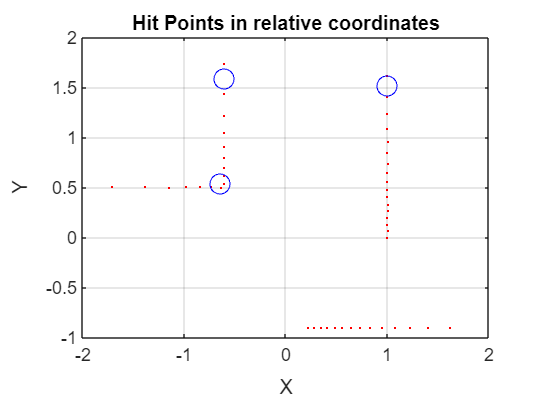

figure ();
plot(point_rel(:, 1), point_rel(:, 2), '.','Color','red', 'MarkerSize', 3);
hold on;
title('Hit Points in relative coordinates');
xlabel('X');
ylabel('Y');
grid on;

for index=1:length(Landmarks_Matrix_clean(:,1))

    plot(Landmarks_Matrix_clean(index,5), Landmarks_Matrix_clean(index,6), 'o','Color','blue', 'MarkerSize', 10, 'DisplayName', 'Old');

end
hold off

Remove type 3 end point

% indici_endp = any(Landmarks_Matrix_clean(:, 5) ~= 3, 2);
% Landmarks_Matrix_clean = Landmarks_Matrix_clean(indici_endp, :); % remove because they were putted only for visualization


## SIMULATION + RRT TREE GENERATION

Combined exploration movements

Drones set up with their specifications

% n = 2; % Number of drones
% Drone = struct(); %New struct
% 
% for i = 1:n % compute for each drone
% 
%     % Define drone specifications such as name and color
%     drone_name = ['Drone_' num2str(i)];
%     Drone.(drone_name).color = rand(1,3); %Drone and scanning color
% 
%     %RRT point position
%     Drone.(drone_name).RRT.map_point = [rand() * x_map_size, rand() * y_map_size]; % first corresppond to the starting_point
% 
%     while isInObstacle(Drone.(drone_name).RRT.map_point,inflated_obstacles) == true
%         % If the random starting point position is inside obstacles,
%         % calculate another point
%         Drone.(drone_name).RRT.map_point =[rand() * x_map_size, rand() * y_map_size];
%     end
% 
%     Drone.(drone_name).RRT.parent_indices = 0;  % Indices numbers to link the points of the trees
%     Drone.(drone_name).RRT.iter_res = 10; % number of iteration for each time istant of simulation
% 
%     %Lidar parameters specifications
%     Drone.(drone_name).Lidar.lidar_angles = linspace(0, 360, 100);  % Number of rays [-]
%     Drone.(drone_name).Lidar.max_range = 2;                         % Maximum length measurement [m]
%     Drone.(drone_name).Lidar.lidar_dist_res = 0.01;                 % Distance measurement resolution [m]
% 
%     %Consensous
%     Drone.(drone_name).Cons.Scanned = zeros(10000,2);
%     Drone.(drone_name).Cons.Adj = zeros(n, n);
%     Drone.(drone_name).Cons.nMsg = 10;
%     Drone.(drone_name).Cons.Degree = zeros(1, n);
%     Drone.(drone_name).Cons.Flag = 0;
% end

START THE DRONES SIMULATION

% %% RRT initialization
% 
% % Simulation setup
% SetUp.Dt = 1; % [s]
% setUp.MaxTime = 30;
% SetUp.Time = 0:SetUp.Dt:setUp.MaxTime; % [s]
% 
% % RRT tree generation
% for t = 0:SetUp.Dt:setUp.MaxTime %time simulation
% 
%     figure(4);
%     for j = 1:size(obstacles, 1)
%         rectangle('Position', obstacles(j, :), 'FaceColor', '#0072BD');
%         hold on;
%     end
%     for j = 1:size(inflated_obstacles, 1)
%         rectangle('Position', inflated_obstacles(j, :), 'EdgeColor', 'k', 'LineStyle', '--');
%         %hold on;
%     end
%     grid on;
%     axis equal; 
%     xlabel('X [m]');
%     ylabel('Y [m]');
%     xlim([-inflate x_map_size + inflate]);
%     ylim([-inflate y_map_size + inflate]);
%     title('Combined RRTs starting point test');
% 
% 
% 
%     for k = 1:n %number of drones
%         drone_name = ['Drone_' num2str(k)];
% 
%         for i = 2:Drone.(drone_name).RRT.iter_res %number of iterations
% 
%             flag1 = true;
%             flag2 = true;
% 
%             while flag1 == true || flag2 == true
%                 random_point = [rand() * x_map_size, rand() * y_map_size];
% 
%                 if isInObstacle(random_point, inflated_obstacles)
%                     flag1 = true;
%                 else
%                     flag1 = false;
%                 end
% 
%                 % Find nearest point wrt RRT tree
%                 distances = sqrt(sum((Drone.(drone_name).RRT.map_point - random_point).^2, 2));
%                 [min_distance, nearest_idx] = min(distances);
% 
%                 % Identify new RRT point
%                 direction = random_point - Drone.(drone_name).RRT.map_point(nearest_idx, :);
%                 unit_direction = direction / norm(direction);
%                 new_point = Drone.(drone_name).RRT.map_point(nearest_idx, :) + step_size * unit_direction;
% 
%                 % Check compenetrarion of new point wrt the obstacles
%                 if isInObstacle(new_point, inflated_obstacles)
%                     flag2 = true;
%                 else
%                     flag2 = false;
%                 end
%             end
%             % Add the new point to the RRT tree
%             Drone.(drone_name).RRT.map_point = [Drone.(drone_name).RRT.map_point; new_point];
%             Drone.(drone_name).RRT.current_position = new_point;
%             Drone.(drone_name).RRT.parent_indices = [Drone.(drone_name).RRT.parent_indices; nearest_idx];
%         end
% 
% 
%         for j = 2:size(Drone.(drone_name).RRT.map_point, 1)
%             figure(4);
%             if j==2
% 
%                 % Plot the starting point
%                 plot(Drone.(drone_name).RRT.map_point(Drone.(drone_name).RRT.parent_indices(j), 1), Drone.(drone_name).RRT.map_point(Drone.(drone_name).RRT.parent_indices(j), 2),...
%                     'Color', 'black', 'Marker' , 'o');
%                 % Plot all the other points
%                 plot([Drone.(drone_name).RRT.map_point(Drone.(drone_name).RRT.parent_indices(j), 1), Drone.(drone_name).RRT.map_point(j, 1)], ...
%                  [Drone.(drone_name).RRT.map_point(Drone.(drone_name).RRT.parent_indices(j), 2), Drone.(drone_name).RRT.map_point(j, 2)], 'LineStyle', '-', 'Color', 'black', 'Marker' , '.');
% 
% 
%             else
%                 plot([Drone.(drone_name).RRT.map_point(Drone.(drone_name).RRT.parent_indices(j), 1), Drone.(drone_name).RRT.map_point(j, 1)], ...
%                  [Drone.(drone_name).RRT.map_point(Drone.(drone_name).RRT.parent_indices(j), 2), Drone.(drone_name).RRT.map_point(j, 2)], 'LineStyle', '-', 'Color', Drone.(drone_name).color, 'Marker' , '.');
%             end
% 
%         end
% 
%         % Reset the old starting point
%         Drone.(drone_name).RRT.map_point = [0,0];
%         Drone.(drone_name).RRT.parent_indices = 0;
% 
%         % Reconstruct a new starting point
%         Drone.(drone_name).RRT.map_point = [rand() * x_map_size, rand() * y_map_size]; 
%         while isInObstacle(Drone.(drone_name).RRT.map_point,inflated_obstacles) == true
%             Drone.(drone_name).RRT.map_point =[rand() * x_map_size, rand() * y_map_size];
%         end
% 
%     end
% 
%     % Print the frame on the screen
%     pause (0.3);
%     if t < (setUp.MaxTime - SetUp.Dt) % if not do not delete last frame
%         clf(figure(4));
%     end
% end
% hold off;